# EXP1-Alireza Pazouki

## plot & stem commands

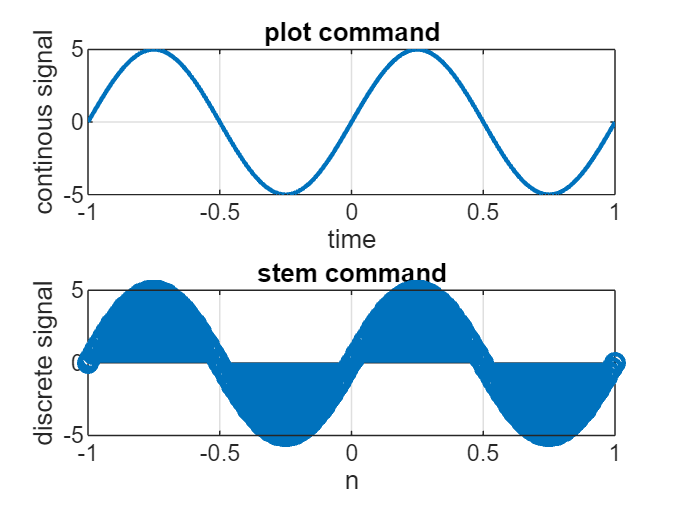

clc; clear; close;
t = -1 : 0.01 : 1 ; %second
A = 5; %hz
f = 1;
w = 2*pi*f;
signal = A*sin(w*t);

figure(1)

subplot(2,1,1)
plot(t,signal,'LineWidth',1.5)
xlabel('time')
ylabel('continous signal')
title('plot command')
grid on

subplot(2,1,2)
stem(t,signal,'LineWidth',1.5)
xlabel('n')
ylabel('discrete signal')
title('stem command')
grid on

## subplot command

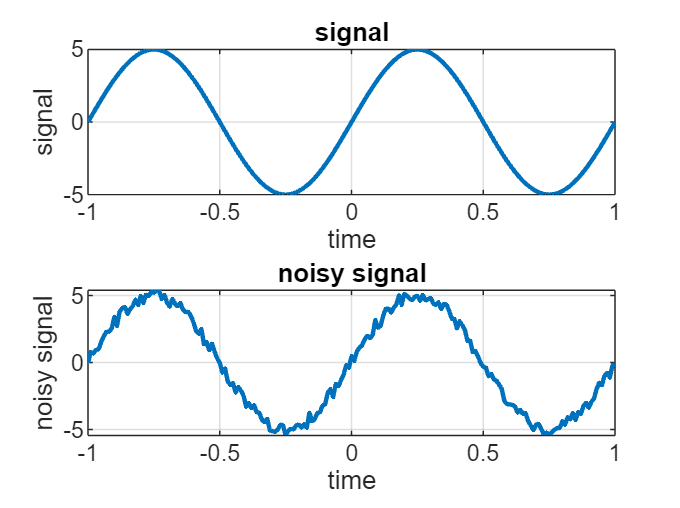


%n = find(t==0.5 | t==-0.5);
noise = rand(size(signal)) - 0.5;
noisy_signal = signal + noise;

figure(2) 

subplot(2,1,1)
plot(t,signal,'LineWidth',1.5)
xlabel('time')
ylabel('signal')
title('signal')
grid on

subplot(2,1,2)
plot(t,noisy_signal,'LineWidth',1.5)
xlabel('time')
ylabel('noisy signal')
title('noisy signal')
grid on

## conv

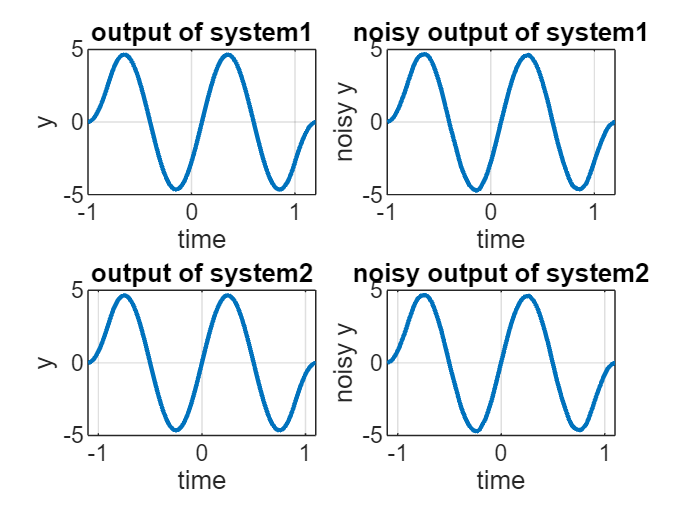

h1 = 1/21 * ones(1,21); % 0 -> 20
h2 = 1/21 * ones(1,21); % -10 -> 10
y = conv(h1,signal);
noisy_y = conv(h1,noisy_signal);
t_y = -1: 0.01: 1 + ( length(h1) - 1)*0.01;

figure(3)

subplot(2,2,1)
plot(t_y,y,'LineWidth',1.5)
xlabel('time')
ylabel('y')
title('output of system1')
grid on

subplot(2,2,2)
plot(t_y,noisy_y,'LineWidth',1.5)
xlabel('time')
ylabel('noisy y')
title('noisy output of system1')
grid on

subplot(2,2,3)
plot(t_y - 10*0.01 ,y,'LineWidth',1.5)
xlabel('time')
ylabel('y')
title('output of system2')
grid on

subplot(2,2,4)
plot(t_y - 10*0.01 ,noisy_y,'LineWidth',1.5)
% t_y minus 10 step time (shift in input is eqiuvalant
% to shift in output in LTI systems)
xlabel('time')
ylabel('noisy y')
title('noisy output of system2')
grid on

## filter command

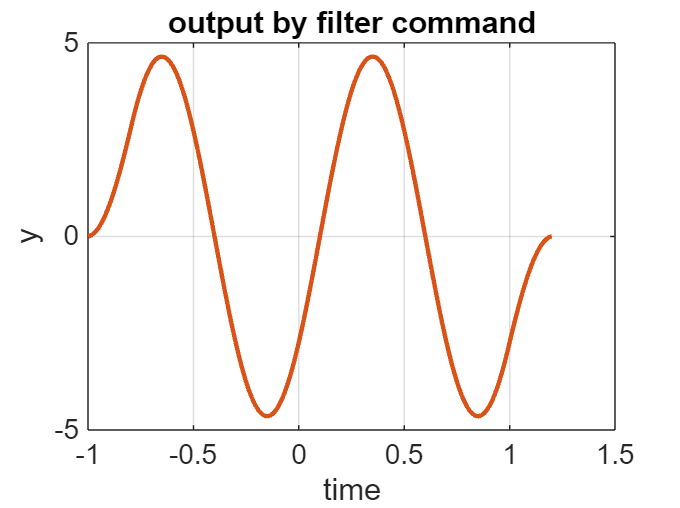

out = filter(h1,1, signal);
noisy_out = filter(h1,1, noisy_signal);

figure(4)

plot(t,out,'LineWidth',1.5)
hold on
plot(t_y, y, 'LineWidth',1.5)
xlabel('time')
ylabel('y')
title('output by filter command')
grid on

## define function

function x = singen(w,n)
n = 0:N-1;
x = sin(w*n);
syms singen(w,n) w n
singen(w,n) = sin(w.*(1:n))  ;
end

## aliasing in time

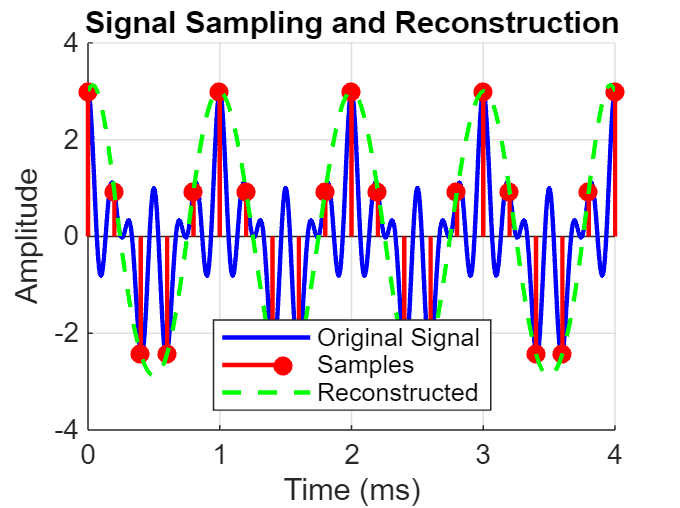

fs = 5000;
t_total = 4e-3;
t_continuous = 0:1e-6:t_total;

f1 = 1000;
f2 = 4000;
f3 = 6000;

x_continuous = cos(2*pi*f1*t_continuous) + ...
               cos(2*pi*f2*t_continuous) + ...
               cos(2*pi*f3*t_continuous);

Ts = 1/fs;
t_sampled = 0:Ts:t_total;
x_sampled = cos(2*pi*f1*t_sampled) + ...
            cos(2*pi*f2*t_sampled) + ...
            cos(2*pi*f3*t_sampled);

t_reconstructed = t_continuous; 
x_reconstructed = zeros(size(t_reconstructed));

for n = 1:length(t_sampled)
    sinc_term = sinc((t_reconstructed - (n-1)*Ts)/Ts);
    x_reconstructed = x_reconstructed + x_sampled(n) * sinc_term;
end

figure;
hold on;
plot(t_continuous*1000, x_continuous, 'b', 'LineWidth', 1.5, 'DisplayName', 'Original Signal');
stem(t_sampled*1000, x_sampled, 'r', 'filled', 'LineWidth', 1.5, 'MarkerSize', 5, 'DisplayName', 'Samples');
plot(t_reconstructed*1000, x_reconstructed, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Reconstructed');
xlabel('Time (ms)');
ylabel('Amplitude');
title('Signal Sampling and Reconstruction');
legend('Location', 'best');
grid on;
hold off;

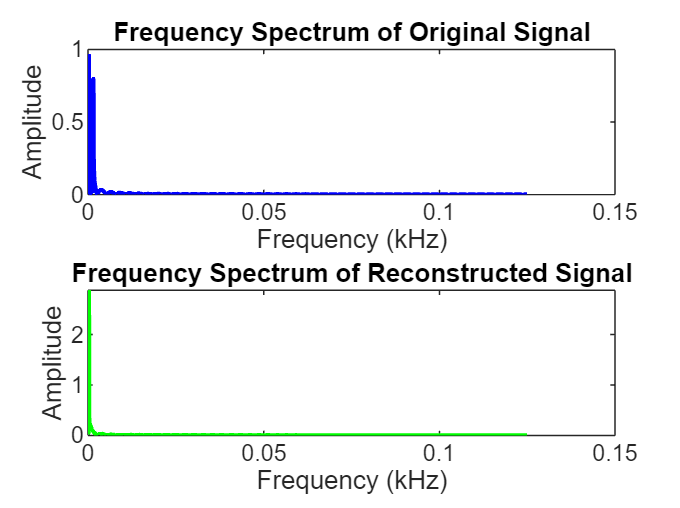


NFFT = 2^nextpow2(length(x_continuous));
f = (0:NFFT/2-1)*(1/(t_total)/NFFT);

X_continuous = fft(x_continuous, NFFT);
X_reconstructed = fft(x_reconstructed, NFFT);

figure;
subplot(2,1,1);
plot(f/1000, 2*abs(X_continuous(1:NFFT/2))/NFFT, 'b', 'LineWidth', 1.5);
title('Frequency Spectrum of Original Signal');
xlabel('Frequency (kHz)');
ylabel('Amplitude');

subplot(2,1,2);
plot(f/1000, 2*abs(X_reconstructed(1:NFFT/2))/NFFT, 'g', 'LineWidth', 1.5);
title('Frequency Spectrum of Reconstructed Signal');
xlabel('Frequency (kHz)');
ylabel('Amplitude');

## aliasing in frequency

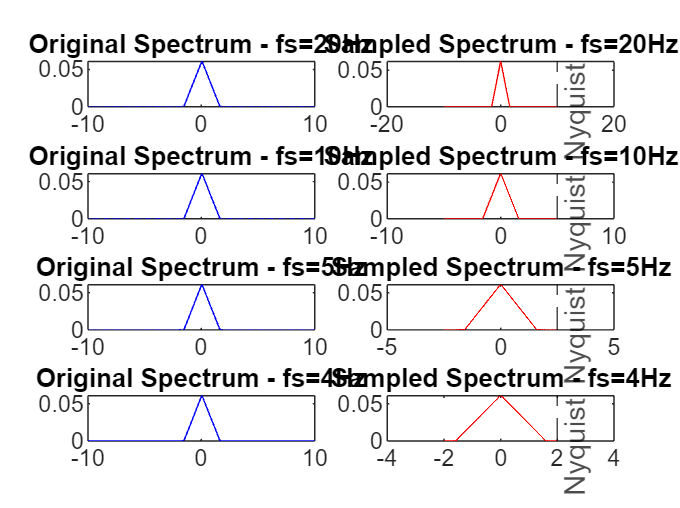

t = -5:0.01:5;
x = sinc(5*t/pi).^2;

fs = [20, 10, 5, 4];
NFFT = 2^nextpow2(length(t));

figure;
for i = 1:length(fs)
    Ts = 1/fs(i);
    t_sampled = -5:Ts:5;
    x_sampled = sinc(5*t_sampled/pi).^2;
    
    X_original = fft(x, NFFT);
    f_original = linspace(-1/(2*0.01), 1/(2*0.01), NFFT);
    
    X_sampled = fft(x_sampled, NFFT);
    f_sampled = linspace(-fs(i)/2, fs(i)/2, NFFT);
    
    subplot(4,2,2*i-1);
    plot(f_original, fftshift(abs(X_original)/NFFT), 'b');
    xlim([-10 10]);
    title(['Original Spectrum - fs=', num2str(fs(i)), 'Hz']);
    
    subplot(4,2,2*i);
    plot(f_sampled, fftshift(abs(X_sampled)/length(x_sampled)), 'r');
    hold on;
    xline(fs(i)/2, '--k', 'Nyquist');
    xlim([-fs(i) fs(i)]);
    title(['Sampled Spectrum - fs=', num2str(fs(i)), 'Hz']);
    hold off;
end

## aliasing in frequency part 2

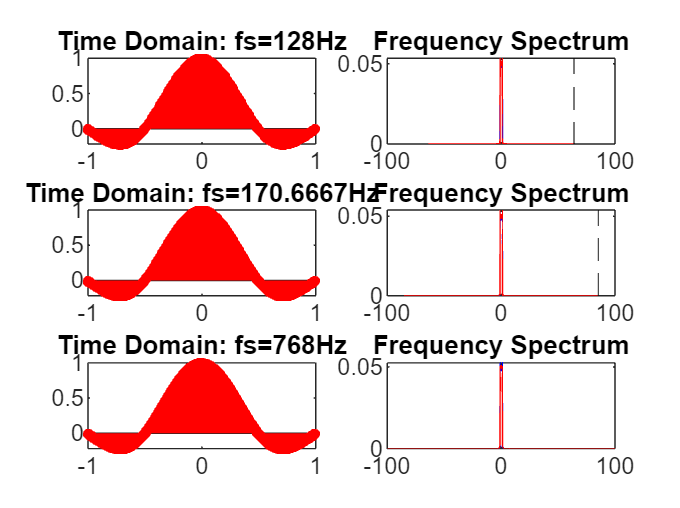

t_continuous = -5:0.01:5;
x_continuous = sinc(2*t_continuous);

fs_base = 256;
ratios = [1/2, 2/3, 3];
fs_values = fs_base * ratios;

figure;
for i = 1:length(fs_values)
    fs = fs_values(i);
    Ts = 1/fs;
    t_sampled = -5:Ts:5;
    x_sampled = sinc(2*t_sampled);
    
    subplot(3,2,2*i-1);
    plot(t_continuous, x_continuous, 'b');
    hold on;
    stem(t_sampled, x_sampled, 'r', 'filled', 'MarkerSize', 3);
    xlim([-1 1]);
    title(['Time Domain: fs=', num2str(fs), 'Hz']);
    
    NFFT = 2^nextpow2(length(x_continuous));
    f_continuous = linspace(-50, 50, NFFT);
    X_continuous = fft(x_continuous, NFFT);
    subplot(3,2,2*i);
    plot(f_continuous, fftshift(abs(X_continuous)/NFFT), 'b');
    hold on;
    
    NFFT_sampled = 2^nextpow2(length(x_sampled));
    f_sampled = linspace(-fs/2, fs/2, NFFT_sampled);
    X_sampled = fft(x_sampled, NFFT_sampled);
    plot(f_sampled, fftshift(abs(X_sampled)/length(x_sampled)), 'r');
    xline(fs/2, '--k');
    xlim([-100 100]);
    title('Frequency Spectrum');
end

## **Filter Bank**

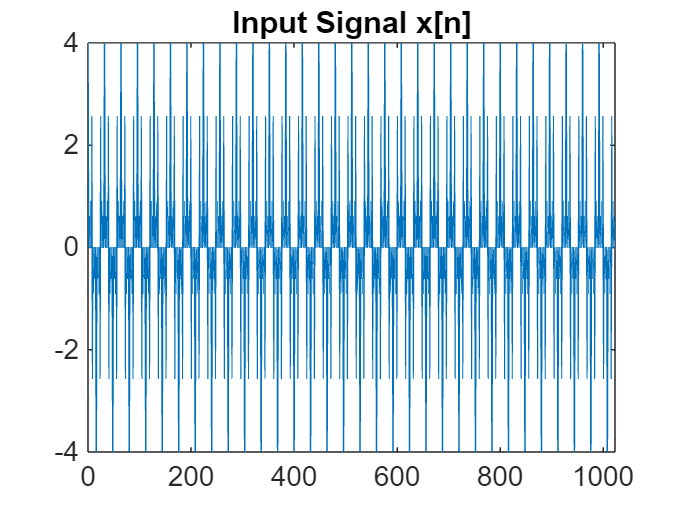

clc;
clear;
close all;
N = 1024;
n = 0:N-1;

f1 = pi/16;
f2 = 5*pi/16;
f3 = 9*pi/16;
f4 = 13*pi/16;

x = cos(f1*n) + cos(f2*n) + cos(f3*n) + cos(f4*n);

figure;
plot(n,x);
title('Input Signal x[n]');

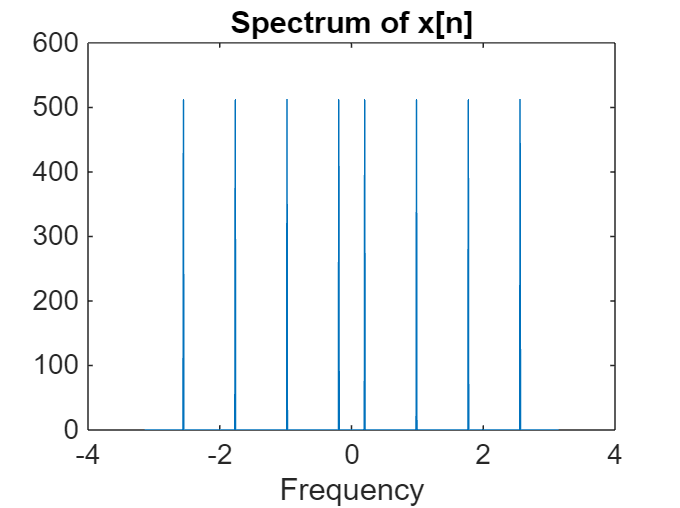


X = fftshift(fft(x));
f = linspace(-pi, pi, N);

figure;
plot(f, abs(X));
title('Spectrum of x[n]');
xlabel('Frequency');

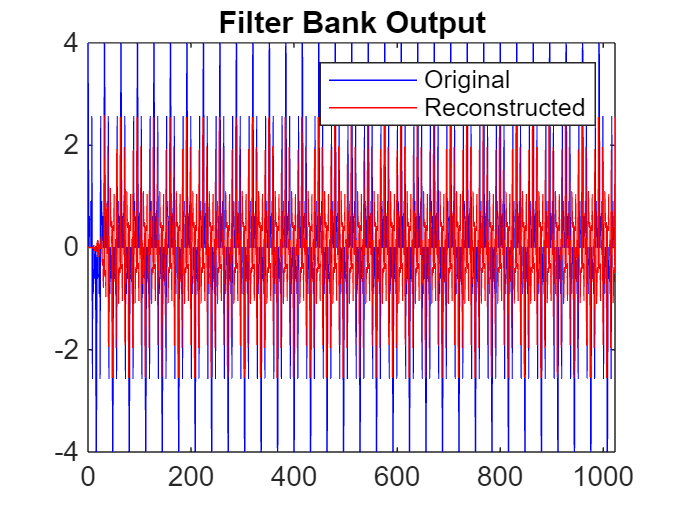


%analysis_filters = xlsread('filters.xls', 'Sheet2');
%synthesis_filters = xlsread('filters.xls', 'Sheet1');
analysis_filters = readmatrix('filters.xls', 'Sheet', 'Sheet2');
synthesis_filters = readmatrix('filters.xls', 'Sheet', 'Sheet1');


for k = 1:4
    h_analysis{k} = analysis_filters(k,:);
    y{k} = filter(h_analysis{k}, 1, x);
end

for k = 1:4
    y_ds{k} = downsample(y{k}, 4);
end

y_ds{1} = 0 * y_ds{1};
y_ds{2} = y_ds{2};
y_ds{3} = 0.5 * y_ds{3};
y_ds{4} = y_ds{4};

for k = 1:4
    y_us{k} = upsample(y_ds{k}, 4);
end

for k = 1:4
    h_syn{k} = synthesis_filters(k,:);
    z{k} = filter(h_syn{k}, 1, y_us{k});
end
%comparison in time domain
y_out = z{1} + z{2} + z{3} + z{4};

figure;

plot(n, x, 'b'); hold on;
plot(n, y_out, 'r');
legend('Original','Reconstructed');
title('Filter Bank Output');

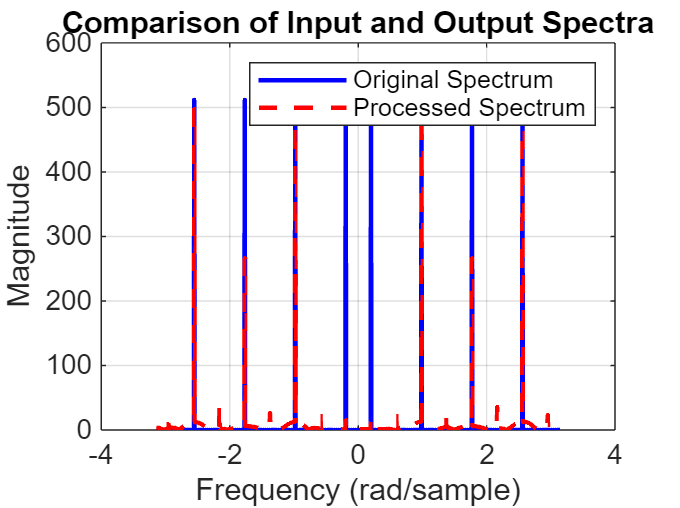

%comparison of outputs in frequency domain
Y_OUT = fftshift(fft(y_out));

figure;
plot(f, abs(X), 'b', 'LineWidth', 1.5); hold on;
plot(f, abs(Y_OUT), 'r--', 'LineWidth', 1.5);
title('Comparison of Input and Output Spectra');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude');
legend('Original Spectrum', 'Processed Spectrum');
grid on;

- **Continuous Signal:** I created `x(t) = sinc(2t)` with fine time steps (0.01) from -5 to 5 seconds to simulate an analog signal.

- **Sampling Rates:** Calculated sampling frequencies as `128 Hz`, `~170.67 Hz`, and `768 Hz` based on ratios of 256 Hz.

- **Sampling:** For each `fs`, I sampled `x(t)` at intervals `Ts = 1/fs`.

- **Time Plots:** Plotted the continuous signal (blue) and superimposed samples (red stems) in the left column.

- **FFT Analysis:** Computed FFT for both continuous and sampled signals. Normalized magnitudes and aligned frequency axes.

- **Frequency Plots:** Overlaid spectra (blue=original, red=sampled) in the right column. Added Nyquist frequency markers (black dashed).

- **Visual Tuning:** Adjusted axis limits to focus on key regions (-1 to 1 sec for time, -100 to 100 Hz for frequency).

- In section 9 of the procedure, the `readmatrix` function was used instead of the older `xlsread` command because the software no longer supports `xlsread` for Excel files. The same results were obtained using `readmatrix`. The original `xlsread` line has been kept in the code as a comment so that it can be tested on another system if needed, indicating that the issue was not related to the code itself.